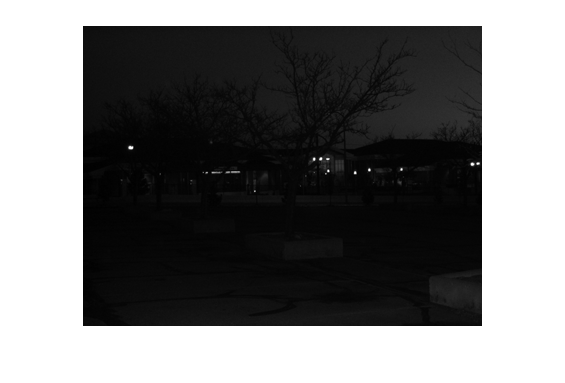

img1 = imread('C:\Users\Admin\OneDrive - Indian Institute of Technology Bombay\CS663\HW2\HW2\LC1.png');
img2 = imread('C:\Users\Admin\OneDrive - Indian Institute of Technology Bombay\CS663\HW2\HW2\LC2.jpg');

% Applying global histogram equalization
img1_global_eq = histeq(img1);
img2_global_eq = histeq(img2);

% Apply CLAHE (local histogram equalization) to the images with different window sizes
img1_win_7x7 = adapthisteq(img1, 'NumTiles', [7 7], 'ClipLimit', 0.01);
img1_win_31x31 = adapthisteq(img1, 'NumTiles', [31 31], 'ClipLimit', 0.01);
img1_win_51x51 = adapthisteq(img1, 'NumTiles', [51 51], 'ClipLimit', 0.01);
img1_win_71x71 = adapthisteq(img1, 'NumTiles', [71 71], 'ClipLimit', 0.01);

img2_win_7x7 = adapthisteq(img2, 'NumTiles', [7 7], 'ClipLimit', 0.01);
img2_win_31x31 = adapthisteq(img2, 'NumTiles', [31 31], 'ClipLimit', 0.01);
img2_win_51x51 = adapthisteq(img2, 'NumTiles', [51 51], 'ClipLimit', 0.01);
img2_win_71x71 = adapthisteq(img2, 'NumTiles', [71 71], 'ClipLimit', 0.01);

% Display each result in a separate interactive figure window for Image 1
figure('Name', 'Original Image 1', 'NumberTitle', 'off');
imshow(img1);

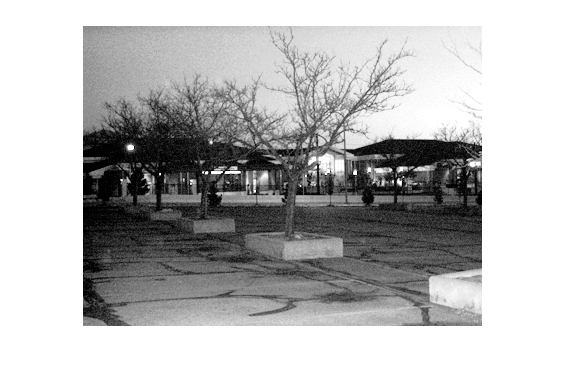


figure('Name', 'Global Histogram Equalization - Image 1', 'NumberTitle', 'off');
imshow(img1_global_eq);

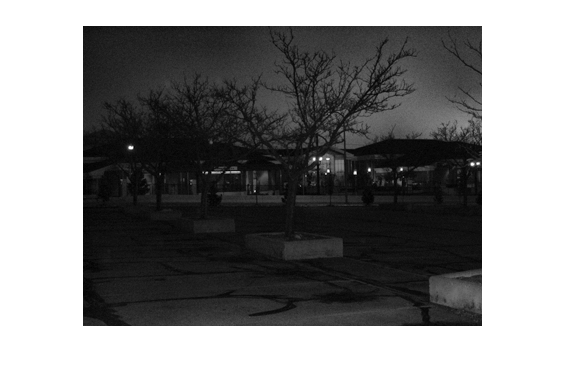


figure('Name', 'Local EQ (WIN 7x7) - Image 1', 'NumberTitle', 'off');
imshow(img1_win_7x7);

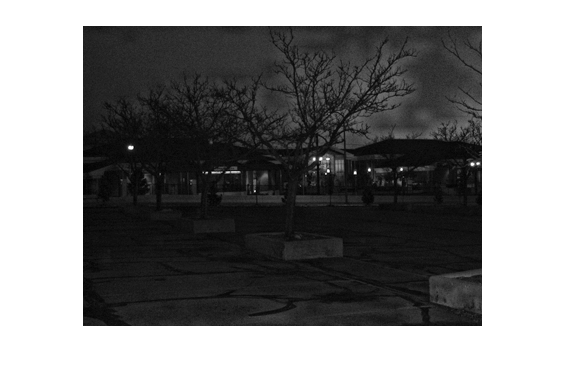


figure('Name', 'Local EQ (WIN 31x31) - Image 1', 'NumberTitle', 'off');
imshow(img1_win_31x31);

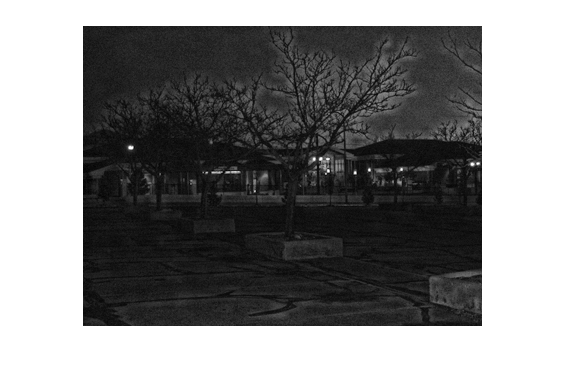


figure('Name', 'Local EQ (WIN 51x51) - Image 1', 'NumberTitle', 'off');
imshow(img1_win_51x51);

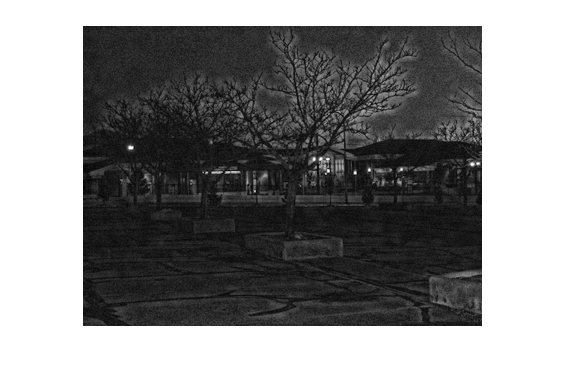


figure('Name', 'Local EQ (WIN 71x71) - Image 1', 'NumberTitle', 'off');
imshow(img1_win_71x71);

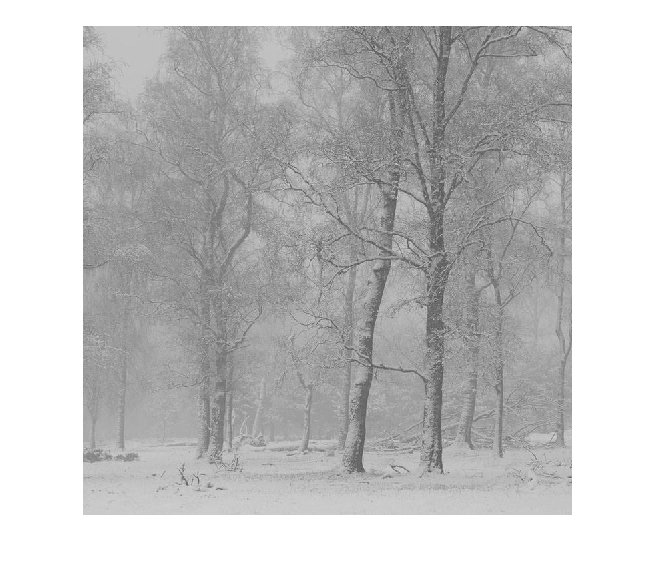


% Display each result in a separate interactive figure window for Image 2
figure('Name', 'Original Image 2', 'NumberTitle', 'off');
imshow(img2);

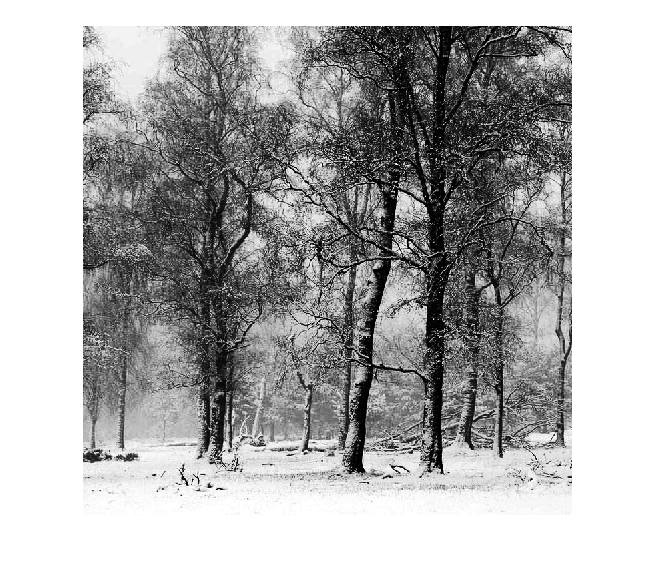


figure('Name', 'Global Histogram Equalization - Image 2', 'NumberTitle', 'off');
imshow(img2_global_eq);

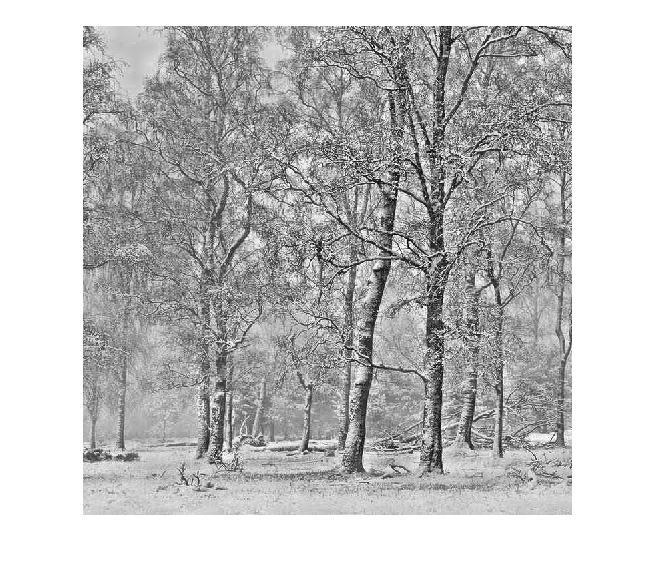


figure('Name', 'Local EQ (WIN 7x7) - Image 2', 'NumberTitle', 'off');
imshow(img2_win_7x7);

figure('Name', 'Local EQ (WIN 31x31) - Image 2', 'NumberTitle', 'off');
imshow(img2_win_31x31);


figure('Name', 'Local EQ (WIN 51x51) - Image 2', 'NumberTitle', 'off');
imshow(img2_win_51x51);

figure('Name', 'Local EQ (WIN 71x71) - Image 2', 'NumberTitle', 'off');
imshow(img2_win_71x71);
